## Damage indicator (DI) calculation for single and multiple-truck events

The purpose of this code is to compute the damage indicator values for the 3-axle truck for single and multiple-truck events. As an example, this is made for the 3-axle truck but can easily be modified for other trucks (4-axle, 5-axle) as well. The damage indicator is defined and utilized in Chapter 4 of the dissertation.

For this, the responses associated with single and multiple 3-axle events on lane 2 and on the bridge with a certain damage scenario are loaded and DI values are computed using a pre-computed Ref IL. Ref ILs are already computed using a seperate code.

In this code, two functions are needed, one for A_MATRIX and one for B_MATRIX. Please see chapter 2 in my disertation for their definitions. Make sure that these two functions are in the file path. In all codes A_MATRIX and B_MATRIX are not needed to be changed and they are the same for all codes.


clear;
close;
clc;

## Loading the data

## Test 1: Single 3-axle on lane 2 and on the bridge with damage scenario 12

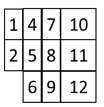

Here we first load the data for the single 3-axle on lane 2 and on the damaged bridge. '6035_Dam12_Single3axle.txt' means the strain is extracted from node 6035 in CSI bridge software. Node 6035 is approximately where max local strain happens.

Dam12 means that the strain respons is for damage scenario 12. See the damage scenario numbers in the picture shown above. Note that the numbers associated with damage scenarios are different than the numbers in my dissertation. This picture is well-explained in my PhD dissertation. You can easily change the damage scenario number by changing Dam12 to Dam1, Dam2, etc in the code below:

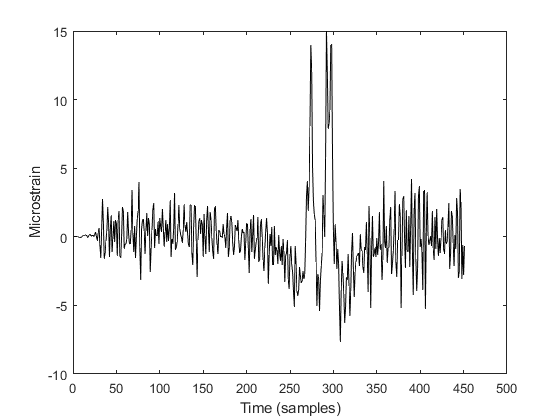


Data9 = textread('6035_Dam12_Single3axle.txt');

plot(Data9,'k', 'Linewidth', 1)
xlabel('Time (samples)')
ylabel('Microstrain')

Test9_st40=Data9;

Test9_st40=Test9_st40';


Here I am isolating the peaks manually to later use only movemean function on other parts of response. The purpose is to keep the peaks as it is (since they are not usually noisy) and to only make other parts smooth. Another way is to use other denoising tecniques such as wavelet etc. My other coded (included in the code folder) has the wavelet denoising approach.

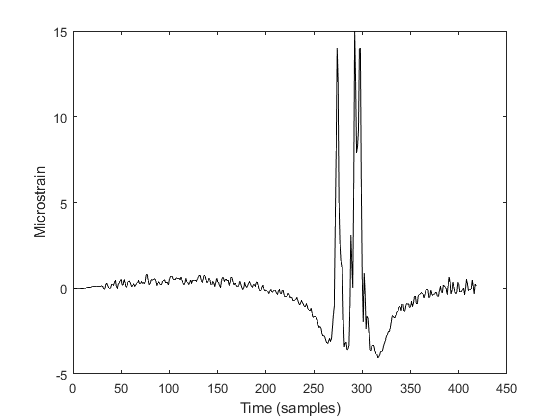



T1=Test9_st40(1:271);
T2=Test9_st40(272:279);
T3=Test9_st40(280:286);
T4=Test9_st40(287:303);
T5=Test9_st40(304:end-33);
T1 = movmean(T1,[10 0]);
T3 = movmean(T3,[10 0]);
T5 = movmean(T5,[10 0]);


Test9_st40=[T1 T2 T3 T4 T5];
Test9_st40=Test9_st40';

% Now, lets plot the smooth strain response

plot(Test9_st40,'k', 'Linewidth', 1)
xlabel('Time (samples)')
ylabel('Microstrain')

## Inputs

Here we get the truck information. Please see the first paper (experimental case study) or my PhD dissertation (chapter 2) for details and to know what these parameters are. I have also commented them below for clarification



N_T9=3;          %% the number of axles
v1_T9=25;        %% speed m/s
f_T9=100;        %% sampling rate (Hz)
d1_T9=0;         %% the distance of the first axle from the first axle (m) --> This is always zero
d2_T9=4.5;       %% the distance of the second axle from the first axle (m) 
d3_T9=1.31;      %% the distance of the third axle from the first axle (m) 


% Axle weights

Weights_T9=[9.1 7.1 7.1];

% D vector using the d values already defined 

D1_vec_T9=[d1_T9 d1_T9+d2_T9 d1_T9+d2_T9+d3_T9];

% Calculating c values based on speed, sampling rate, and d values

c1_T9=D1_vec_T9(1)*f_T9/v1_T9;
c2_T9=D1_vec_T9(2)*f_T9/v1_T9;
c3_T9=D1_vec_T9(3)*f_T9/v1_T9;


C1_vec_T9=round([c1_T9 c2_T9 c3_T9]);

[row1_T9 col1_T9]=size(Test9_st40);
k1_T9=row1_T9;                        %% Number of scans 


This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data) and returns the Matrix A. This matrix is later used for IL computation.


[A_mat_T9]=A_MATRIX(N_T9,k1_T9,C1_vec_T9,Weights_T9);


## Test 2: Two 3-axle trucks on lane 2 and on the damaged bridge

Here we load the data for two in-one-row 3-axle trucks on lane 2 and on the damaged bridge. All comments are similar to the previous one shown above except for the one explained as follows. 

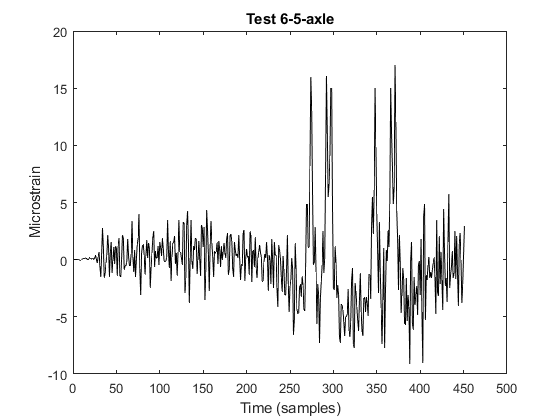



Data1 = textread('6035_Dam12_Multiple3axle.txt');

plot(Data1,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

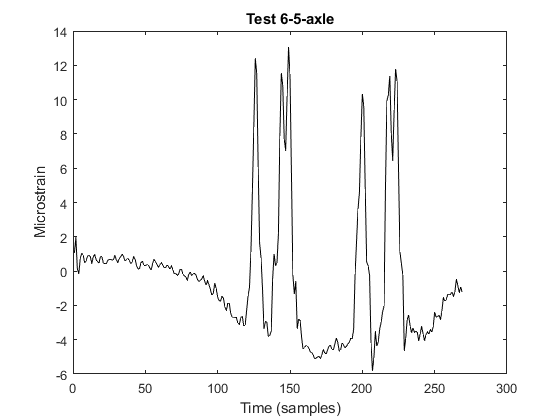


Test1_st40=Data1;

Test1_st40=Test1_st40';

T1=Test1_st40(150:271);
T2=Test1_st40(272:279);
T3=Test1_st40(280:286);
T4=Test1_st40(287:303);
T5=Test1_st40(304:342);

T6=Test1_st40(343:354);
T7=Test1_st40(355:364);
T8=Test1_st40(365:377);
T9=Test1_st40(378:end-33);


T1 = movmean(T1,[10 0]);
T2 = movmean(T2,[2 0]);
T3 = movmean(T3,[10 0]);
T4 = movmean(T4,[2 0]);
T5 = movmean(T5,[10 0]);
T6= movmean(T6,[2 0]);
T7 = movmean(T7,[10 0]);
T8 = movmean(T8,[2 0]);
T9 = movmean(T9,[10 0]);

Test1_st40=[T1 T2 T3 T4 T5 T6 T7 T8 T9];

Test1_st40=Test1_st40';

figure
plot(Test1_st40,'k', 'Linewidth', 1)
title('Test 6-5-axle')
xlabel('Time (samples)')
ylabel('Microstrain')

The envelope function is coded here to remove the global (non-localized) strain response. In this study, it was found that the ``Envelope'' function in MATLAB can successfully satisfy the requirements for global strain removal (explained in my dissertation) when a proper ``peak separation factor (n_p)'' is selected. The MATLAB code prepared for this study automatically checks different. $n_p$ values between 30-50 (found as the most effective range) and chooses the one that generates an envelope with smallest difference from P_1 (explained in my dissertation). To do this, a loop was programmed that changes the np value in each step and chooses the one with the lowest generated P_1 in the modified strain response (the non-localized response removed). 



Cri_1=[];
AA=1;
XX=[30 35 40 45 50];
for BB=1:length(XX)
  [up1,low_test1] = envelope(Test1_st40,XX(BB),'peak');
  param_small = {'Color',[0.9 0.4 0.1],'Linewidth',2};
  
  Test1_st40_TRY=Test1_st40-low_test1;
  Cri_1(AA)=[abs(Test1_st40_TRY(131,1))];
  AA=AA+1;
end
Index = find(Cri_1==min(Cri_1));

if length(Index)>1
    Index=Index(1)
end


[up1,low_test1] = envelope(Test1_st40,XX(Index),'peak');
Test1_st40=Test1_st40-low_test1;



let's plot the modified strain response when the global strain is removed.

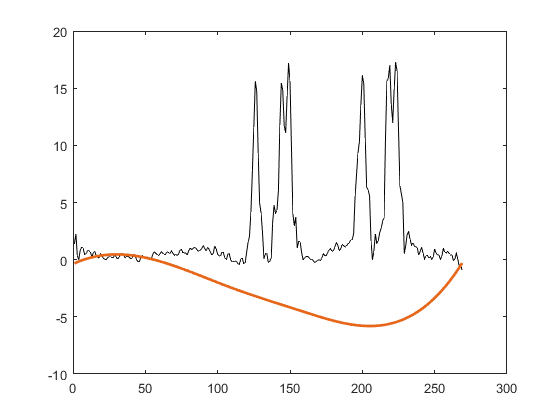


figure
plot(Test1_st40,'k', 'Linewidth', 1)
hold on
plot(low_test1,param_small{:});
hold off

Now, we can easily decompose the strains associated with each truck.

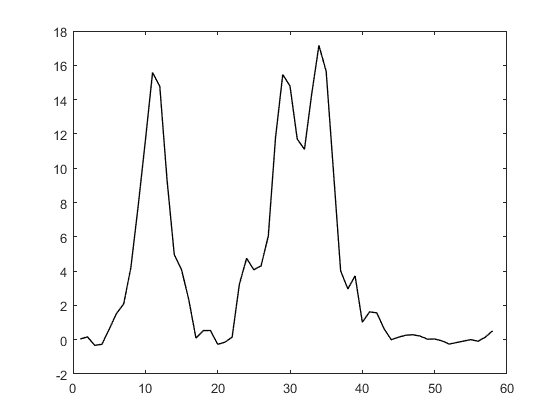


Test1_st40=Test1_st40(116:173);
figure
plot(Test1_st40,'k', 'Linewidth', 1)

## Inputs

This section is the same as previous test. Please see the comments for that test.


N_T1=3;          %% the number of axles
v1_T1=25;     %% m/s
f_T1=100;        %% Hz
d1_T1=0;         %% m
d2_T1=4.5;      %% m
d3_T1=1.31;      %% m



Weights_T1=[9.1 7.1 7.1];

D1_vec_T1=[d1_T1 d1_T1+d2_T1 d1_T1+d2_T1+d3_T1];

c1_T1=D1_vec_T1(1)*f_T1/v1_T1;
c2_T1=D1_vec_T1(2)*f_T1/v1_T1;
c3_T1=D1_vec_T1(3)*f_T1/v1_T1;


C1_vec_T1=round([c1_T1 c2_T1 c3_T1]);

[row1_T1 col1_T1]=size(Test1_st40);
k1_T1=row1_T1;                      %% Total number of scans


This function takes N (the number of axles), K(total number of scans), vector C (created from c1,c2,etc.), Weight vector (created from a truck axle weights which is considered for calibration), and dataaa (strain data)


[A_mat_T1]=A_MATRIX(N_T1,k1_T1,C1_vec_T1,Weights_T1);


## Influence Line 

Now, we calculate the IL lines for the single-truck and multiple-truck events.

Inf_Line9=inv(A_mat_T9'*A_mat_T9)*A_mat_T9'*Test9_st40;
Inf_Line1=inv(A_mat_T1'*A_mat_T1)*A_mat_T1'*Test1_st40;


Not that necessary, but here, I am just smoothing the unnecessary parts of the ILs.


Inf_Line9=Inf_Line9(149:end-1);
Inf_Line9=Inf_Line9';
Inf_Line9=[(movmean(Inf_Line9(1:118),[20 0])) Inf_Line9(119:135) movmean(Inf_Line9(136:end),[0 20])];
Inf_Line1=Inf_Line1';
Inf_Line1=[(movmean(Inf_Line1(1:3),[20 0])) Inf_Line1(4:20) movmean(Inf_Line1(21:end),[0 20])];

## Check the IL

Here I am loading the Ref ILs for single and multiple-truck events. These Ref ILs are already computed using another MATLAB code and per the instruction explained in my dissertation.



REFIL = textread('RefIL_3axle.txt');                        %% Precalculated REF IL for single-truck event
REFIL_multiple = textread('RefIL_3axle - Multiple2.txt');   %% Precalculated REF IL for multiple-truck event


Plot the REF IL for single-truck event vs. the IL of the damaged case

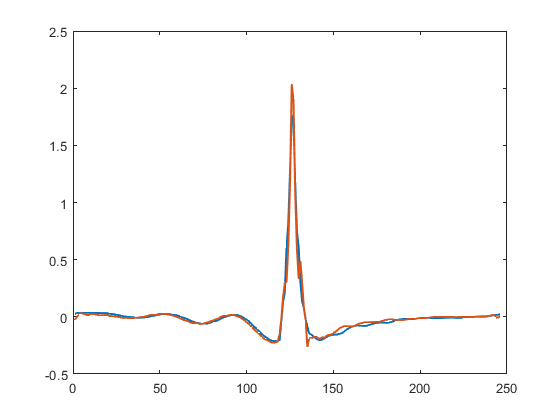


figure
plot(REFIL, 'Linewidth', 1.5)

hold on
plot(Inf_Line9, 'Linewidth', 1.5)

Damage indicator value for single-truck event vs. the damaged case (single-truck event)


BB=0;
for i=1:length(REFIL)
PPP=[REFIL(i)-Inf_Line9(i)]^2;
BB=BB+PPP;
end

DLocator=BB

DLocator = 0.5168

Plot the REF IL for multiple-truck event vs. the IL of the damaged case

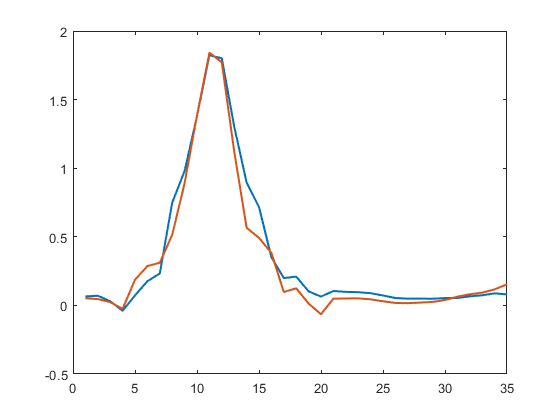

 

figure
plot(REFIL_multiple, 'Linewidth', 1.5)

hold on
plot(Inf_Line1, 'Linewidth', 1.5)

Damage indicator value for multiple-truck event vs. the damaged case (multiple-truck event)



BB=0;
for i=1:length(REFIL_multiple)
PPP=[REFIL_multiple(i)-Inf_Line1(i)]^2;
BB=BB+PPP;
end

DLocator=BB

DLocator = 0.3531